**Practical Problems 5 – Open Root Finding Methods**	

Plotting the function is a good idea to get an idea of where the roots are and provide initial guesses, then the methods can be used to get an accurate estimation. 

You can also substitute your answers back into the equation to see if it is correct (anonymous functions can help with that).

1.Use the **roots** function to find the roots of the polynomial.                              	

p(x) = x^5 - 10x^3 + 21x

p = roots([1, 0, -10, 0, 21, 0]);
disp("Roots of the polynomial:");
disp(p);

2.Create an anonymous function for p(x) and substitute the roots you found in question 1 into it to verify your answer.

p = @(x) x.^5 - 10*x.^3 + 21*x;
roots_p = roots([1, 0, -10, 0, 21, 0]);

for i = 1:length(roots_p)
    root = roots_p(i);
    fprintf('p(%.6f) = %.6f\n', root, p(root))
end

Choose g(x): #1


Iteration 1: x = -0.35653066, Error = 0.85653066
Iteration 2: x = -1.30125121, Error = 0.94472055
Iteration 3: x = -1.98063589, Error = 0.67938468
Iteration 4: x = -3.32443152, Error = 1.34379562
Iteration 5: x = -16.73135494, Error = 13.40692342
Iteration 6: x = -18464116.85717474, Error = 18464100.12581980
Iteration 7: x = -Inf, Error = Inf
Iteration diverged due to infinite value and nan.


Choose g(x): #2


Iteration 1: x = 1.05191761, Error = 0.55191761
Iteration 2: x = 1.18371659, Error = 0.13179898
Iteration 3: x = 1.22059634, Error = 0.03687975
Iteration 4: x = 1.23111758, Error = 0.01052124
Iteration 5: x = 1.23413276, Error = 0.00301518
Iteration 6: x = 1.23499792, Error = 0.00086515
Iteration 7: x = 1.23524625, Error = 0.00024833
Iteration 8: x = 1.23531753, Error = 0.00007128
Iteration 9: x = 1.23533799, Error = 0.00002046
Iteration 10: x = 1.23534387, Error = 0.00000587
Converged to a root: 1.23534387


Choose g(x): #3


Iteration 1: x = 1.38629436, Error = 3.26421845
Iteration 2: x = -2.38591897, Error = 6.87296758
Iteration 3: x = -2.71363840, Error = 1.16612618
Iteration 4: x = -2.51533435, Error = 0.63539786
Iteration 5: x = -2.26783342, Error = 0.38776047
Iteration 6: x = -2.05051802, Error = 0.26672503
Iteration 7: x = -1.86443580, Error = 0.20366300
Iteration 8: x = -1.69935928, Error = 0.17037435
Iteration 9: x = -1.54514668, Error = 0.15491718
Iteration 10: x = -1.39275165, Error = 0.15265781
Iteration 11: x = -1.23360520, Error = 0.16329924
Iteration 12: x = -1.05987666, Error = 0.19075078
Iteration 13: x = -0.87092109, Error = 0.24519554
Iteration 14: x = -0.70993198, Error = 0.34473957
Iteration 15: x = -0.77067795, Error = 0.49088600
Iteration 16: x = -1.25040484, Error = 0.59384340
Iteration 17: x = -1.79000691, Error = 0.55301501
Iteration 18: x = -2.03951440, Error = 0.42619323
Iteration 19: x = -2.05999517, Error = 0.30850245
Iteration 20: x = -1.97973046, Error = 0.22736642
Iteration 

Choose g(x): #4


Iteration 1: x = 2.21306132, Error = 1.71306132
Iteration 2: x = 1.04941812, Error = 1.16364320
Iteration 3: x = 1.33365293, Error = 0.28423481
Iteration 4: x = 1.19758732, Error = 0.13606561
Iteration 5: x = 1.25210836, Error = 0.05452104
Iteration 6: x = 1.22833597, Error = 0.02377239
Iteration 7: x = 1.23835447, Error = 0.01001850
Iteration 8: x = 1.23406933, Error = 0.00428514
Iteration 9: x = 1.23589077, Error = 0.00182144
Iteration 10: x = 1.23511448, Error = 0.00077629
Iteration 11: x = 1.23544495, Error = 0.00033048
Iteration 12: x = 1.23530420, Error = 0.00014076
Iteration 13: x = 1.23536414, Error = 0.00005994
Iteration 14: x = 1.23533861, Error = 0.00002553
Iteration 15: x = 1.23534948, Error = 0.00001087
Iteration 16: x = 1.23534485, Error = 0.00000463
Converged to a root: 1.23534485


3.Use the **roots** function to find the roots of the polynomial (no template). Display only the real roots.         

             

q = roots([-2, 0, -1.5, 0, 0, 10, 2])
q_equation = @(x) -2 * x.^6 - 1.5 * x.^4 + 10*x +2
real_root = q(imag(q) == 0)
fprintf('The roots are %.4f\n', q_equation(real_root))

4.Use the **fzero** function to locate all roots of 

f(x) = e^xcos^2(x) -2 

                                    

on the interval [0,5]. Plot the function with a grid and mark the roots with large green diamonds. For this question make a function file to hold the function. You will have to divide the interval into pieces using an appropriate step size, h. First try h = 2, then plot the function and roots to see if it found them all. If not, adjust your value of h and try again.

func = @(x) exp(x) .* cos(x).^2 - 2;

x_vals = 0:2:5;
roots_found = [];

for i = x_vals
    root = fzero(func, i);
    roots_found = [roots_found, root];
end

roots_found

figure;

x = 0:0.001:5;

Converged to root: 5.49778714


y = func(x);
plot(x, y);
grid on;
hold on;

plot(roots_found, func(roots_found), 'gd', 'MarkerSize', 10);

Converged to root: 5.49778645


Converged to root: 5.49778714


xlabel('x');
ylabel('f(x)');
title('Plot of f(x) with Roots Marked');

% Display the legend
legend('f(x)', 'Roots');

% Set a reasonable y-axis limit for visualization

hold off;

5.Write a script that solves

h(x) = x^2 - x - exp(-x)

using Fixed Point Iteration. Choose your own stopping criteria and keep track of the error at each iteration. Keep in mind that you can choose any of the following 4 formulas for your fixed point iteration:

g(x) = -exp(-x) + x^2

g(x) = (exp(-x) + x) ^ 0.5

g(x) = -log((x^2) - x)

g(x) = 1 + (exp(-x) / x)

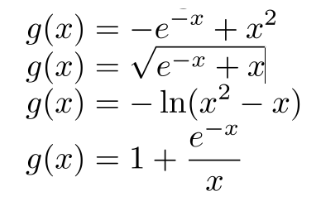                                   

Test all of them to see which work and which don’t.

clf reset

g_functions = {@(x) -exp(-x) + x^2, @(x) (exp(-x) + x) ^ 0.5, @(x) -log(x^2 - x), @(x) 1 + (exp(-x) / x)};

% g = @(x) (exp(-x) + x) ^ 0.5;
for i = 1:length(g_functions)
    x0 = 0.5;
    iterations = 0;
    tolerance = 0.0001;
    g = g_functions{i};
    fprintf('Choose g(x): #%d\n', i);
    while true
        iterations = iterations + 1;
        x = g(x0);
        error = abs(x - x0);
        fprintf('Iteration %d: x = %.8f, Error = %.8f\n', iterations, x, error);
    
        if error < tolerance
            fprintf('Converged to a root: %.8f\n', x);
            break;

Found roots on the interval [-pi, pi]:


        end

   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416    2.3562         0   -3.1416    0.7854   -0.7854   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562


        if isinf(error) || isinf(x)
            break;
        end

        if diff(g(x)) > 1
            error('error slope more than 1')
        end
    
        x0 = x;
    end
end

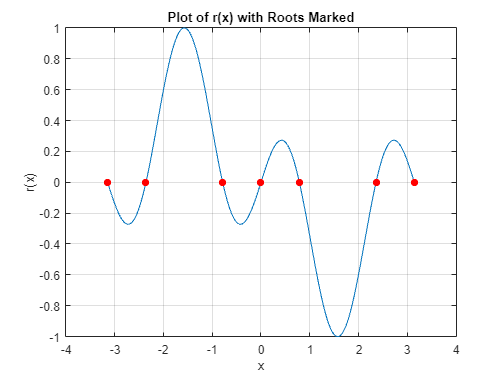

g_functions = {@(x) -exp(-x) + x^2, @(x) (exp(-x) + x) ^ 0.5, @(x) -log(x^2 - x), @(x) 1 + (exp(-x) / x)};
for i = 1:length(g_functions)
    x0 = 0.5;

    max_iterations = 1000;
    tolerance = 0.0001;
    g = g_functions{i};
    fprintf('Choose g(x): #%d\n', i);
    fixedPointIteration(g, x0, 0.00001,max_iterations);
end

6.Write a function that takes an initial guess as input then locates a root of

r(x) = sin(x)cos(2x)

 

using the Newton-Raphson Method. Remember you will have to differentiate the function to get the formula. Choose your own convergence criterion.

r = @(x) sin(x) * cos(2*x);
r_prime = @(x) cos(x) * cos(2*x) - 2 * sin(x) * sin(2*x);

max_iterations = 100;

Converged to root: -3.14159265
Converged to root: -3.14159699
Converged to root: -3.14162740
Converged to root: -3.14159265
Converged to root: -3.14159265
Converged to root: -3.14159265
Converged to root: -3.14159265
Converged to root: -3.14159264
Converged to root: -3.14159260
Converged to root: -3.14159250
Converged to root: -3.14159223
Converged to root: -3.14159163
Converged to root: -3.14159031
Converged to root: -3.14158762
Converged to root: -3.14158233
Converged to root: -3.14157235
Converged to root: -3.14155408
Converged to root: -3.14152151
Converged to root: -3.14159265
Converged to root: -3.14159265
Converged to root: -3.14159265
Converged to root: -3.14159265
Converged to root: -3.14159266
Converged to root: -3.14159268
Converged to root: -3.14159279
Converged to root: -3.14159327
Converged to root: -3.14159551
Converged to root: -3.14160641
Converged to root: -3.14166253
Converged to root: -3.14159265
Converged to root: -3.14159258
Converged to root: -3.14151892
Converge

tolerance = 0.0001;
x0 = 5;

  Columns 1 through 3,276

   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416    2.3562         0   -3.1416    0.7854   -0.7854   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   

for iteration = 1:max_iterations
    r_prime = @(x) cos(x) * cos(2*x) - 2 * sin(x) * sin(2*x);
    x = x0 - (r(x0) / r_prime(x0));
    error = abs(x - x0);

    if error <= tolerance
        x0 = x;
        fprintf('Converged to root: %.8f\n', x0);
        break;
    end

    x0 = x;
end

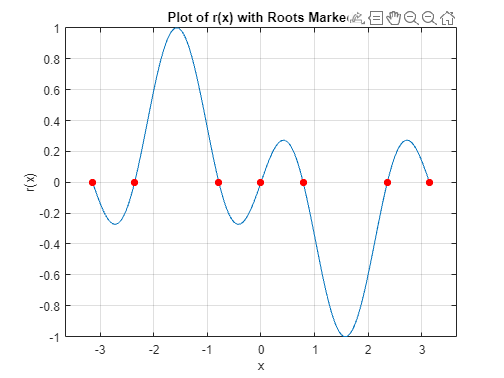

max_iterations = 100;

tolerance = 0.0001;
x0 = 5;

root = newtonRaphson(r, x0, tolerance, max_iterations);
fprintf('Converged to root: %.8f\n', root);

7.Use your function from question 7 to find all roots of r(x) on the interval [–π,π].

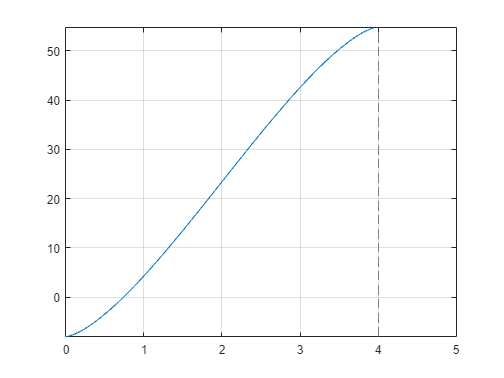

r = @(x) sin(x) .* cos(2*x);

max_iterations = 100;
tolerance = 0.0001;

roots_found = [];

% Iterate through the interval [-pi, pi]
for x0 = -pi:0.01:pi
    for iteration = 1:max_iterations
        r_prime = @(x) cos(x) * cos(2*x) - 2 * sin(x) * sin(2*x);
        x = x0 - (r(x0) / r_prime(x0));
        error = abs(x - x0);


        if error < tolerance
            roots_found = [roots_found, x];
            break;
        end


    {[0.7400 0.7401]}



        x0 = x;

    {[0.7400 0.7401]}



    end
end

% Filter roots to be within the range [-pi, pi]
roots_found = roots_found(abs(roots_found) <= pi);


root_found = 0.7400

% Display the found roots

Converged to root: 0.73996522
Converged to root: 0.74006522


root_found =     0.7400    0.7401


fprintf('Found roots on the interval [-pi, pi]:\n');
disp(roots_found);

% Plot the function r(x) and mark the roots
x_vals = linspace(-pi, pi, 1000);
y_vals = r(x_vals);

figure;
plot(x_vals, y_vals);
hold on;
scatter(roots_found, zeros(size(roots_found)), 'r', 'filled');
hold off;

xlabel('x');
ylabel('r(x)');
title('Plot of r(x) with Roots Marked');
grid on;

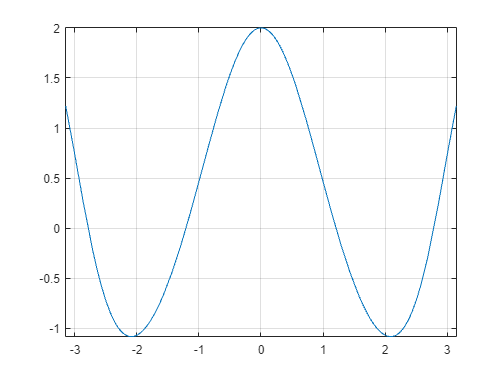

r = @(x) sin(x) .* cos(2*x);

max_iterations = 100;
tolerance = 0.0001;

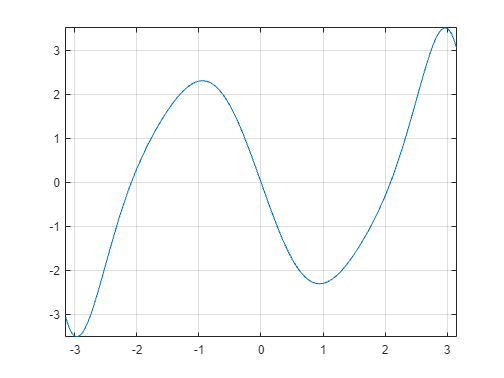

x0 = 5;

for x0 = -pi:0.01:pi
    root = newtonRaphson(r, x0, tolerance, max_iterations);
    roots_found_2 = [roots_found_2, root];
end
% root = newtonRaphson(r, x0, tolerance, max_iterations);
disp(roots_found_2);

x_vals = linspace(-pi, pi, 1000);
y_vals = r(x_vals);

figure;
plot(x_vals, y_vals);
hold on;
xlim([-pi-0.5, pi+0.5])
scatter(roots_found_2, r(roots_found_2), 'r', 'filled');
hold off;


    {[-2.0863 -2.0862]}    {[-9.2654e-05 7.3464e-06]}    {[2.0862 2.0863]}



xlabel('x');
ylabel('r(x)');
title('Plot of r(x) with Roots Marked');
grid on;

8.Write a script that locates all roots of

w(x) = x^3 - 6*x^2 + 10*x -4

using the Bisection Method. Locate brackets by using the incremental search method you wrote before.

% Define the function w(x)
w = @(x) x^3 - 6*x^2 + 10*x - 4;

% Define the range of search and step size
a = -10;
b = 10;
step_size = 0.1;

% Use the incremental search function to find brackets
intervals = incremental_search(w, a, b, step_size);
disp(intervals)

% Tolerance and maximum iterations for the Bisection Method
bisection_tolerance = 0.0001;
bisection_max_iterations = 100;

% Loop through each bracket and apply the Bisection Method
roots_found = [];
for i = 1:size(intervals, 2)
    a = intervals{i}(1);
    b = intervals{i}(2);

   -2.0862



Turning points are : -2.08622606


  -4.2654e-05



Turning points are : 0.00000000


    2.0863



Turning points are : 2.08622606


    root = bisectionMethod(w, a, b, bisection_tolerance, bisection_max_iterations);

   -2.0862    0.0000    2.0862



    roots_found = [roots_found, root];
end

% Display the found roots
fprintf('Found roots:\n');
disp(roots_found);

   -2.0862



Converged to root: -2.08624265


  -4.2654e-05



Converged to root: -0.00004265


    2.0863



Converged to root: 2.08625735


9.The volume of liquid V in a hollow horizontal cylinder of radius r and length L is related to the depth of the liquid h by,

V = (r^2 * cos((r-h) / r)^-1 - (r-h) ((2*r*h)-h^2)^0.5) * L

Determine *h* given *r* = 2m, *L* = 5m, and *V* = 8m.

r = 2; % radius in meters

   -2.0862    0.0000    2.0862



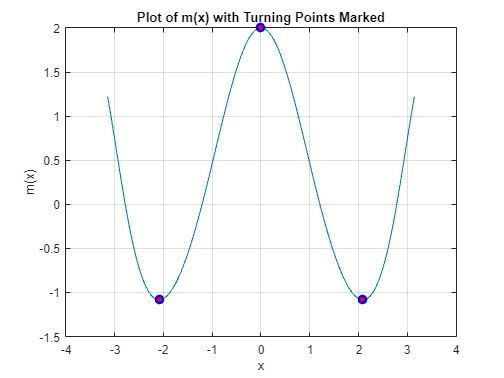

L = 5; % length in meters
V = 8; % volume in cubic meters

% Define the equation in terms of h
equation = @(h) (r.^2 * acos((r - h) / r) - (r - h) .* sqrt(2 * r * h - h.^2)) .* L - V;

syms h_sym;
equation_sym = equation(h_sym);
equation_prime_sym = diff(equation_sym, h_sym);
equation_prime = matlabFunction(equation_prime_sym);

fplot(equation, [0, 5]);
grid on;
a = 0;
b = 5;
step_size = 0.0001;
intervals = incremental_search(equation, a, b, step_size);
disp(intervals)

disp(intervals(1))
% Solve for h using fzero in each interval
max_iterations = 1000;
tolerance = 0.01;


% root_found = []
root_found = fzero(equation, intervals{1})
root_found = newtonRaphson(equation, intervals{1}, 0.00001, 1000)

% for i = 1:length(intervals)
%     a = intervals{i}(1);

%     b = intervals{i}(2);
% 
%     x0 = (a + b) / 2;
%     disp(x0);
% 
%     for iteration = 1:max_iterations
%         x = x0 - (equation(x0) / equation_prime(x0));
%         error = abs(x - x0);
% 
%         if error < tolerance
%             roots_found = [roots_found, x];
%             fprintf('Converged to root: %.8f\n', x);
%             break;
%         end
%     end
% 
%         x0 = x;
% end
% % Display the found roots
% fprintf('Found roots: %.8f \n', roots_found);



10.Determine the location of the horizontal tangents (turning points) of 

on the interval [–π,π]. Plot the figure and mark the turning points with thick, large red circles with blue faces .

m = @(x) cos((x.^2) / 2) + cos(2.*x);

fplot(m, [-pi, pi])
grid on

syms x_sym;
m_sym = m(x_sym);
m_prime_sym = diff(m_sym, 1);
m_prime = matlabFunction(m_prime_sym);

fplot(m_prime, [-pi, pi]);
grid on;
syms x_sym;
m_sym = m(x_sym);
m_double_m_prime_sym = diff(m_sym, 2);
m_double_prime = matlabFunction(m_double_m_prime_sym);

a = -pi;
b = pi;
step_size = 0.0001;
m_intervals = incremental_search(m_prime, a, b, step_size);
disp(m_intervals)
% Solve for h using fzero in each interval
max_iterations = 1000;
tolerance = 0.0001;
turning_points = [];

for i = 1:length(m_intervals)
    a = m_intervals{i}(1);
    b = m_intervals{i}(2);

    x0 = (a + b) / 2;
    disp(x0);

    for iteration = 1:max_iterations
        x = x0 - (m_prime(x0) / m_double_prime(x0));
        error = abs(x - x0);

        if error < tolerance
            turning_points = [turning_points, x];
            fprintf('Turning points are : %.8f\n', x);
            break;
        end
    end

        x0 = x;
end
disp(turning_points)
% Solve for h using fzero in each interval
max_iterations = 1000;
tolerance = 0.0001;
turning_points_2 = [];

for i = 1:length(m_intervals)
    a = m_intervals{i}(1);
    b = m_intervals{i}(2);

    x0 = (a + b) / 2;
    disp(x0);

    turning_points_2 = [turning_points_2, newtonRaphson(m_prime, x0, tolerance, max_iterations)];
end

disp(turning_points_2)

x_vals = linspace(-pi, pi, 1000);
y_vals = m(x_vals);

figure;
plot(x_vals, y_vals);

hold on;

% Mark the turning points with red circles
scatter(turning_points, m(turning_points), 'ro', 'filled', 'MarkerEdgeColor', 'b', 'LineWidth', 2);

hold off;

xlabel('x');
ylabel('m(x)');
title('Plot of m(x) with Turning Points Marked');
grid on;

m = @(x) cos((x.^2) / 2) + cos(2.*x);

fplot(m, [-pi, pi])
grid on
clear x
syms x
m_prime = diff(m, x);

fplot(m_prime, [-pi, pi]);
grid on;